# Diskrete Fourier-Transformation

Wir betrachten eine (reelle) trigonometrische Funktion:

 
$$f(x)=A_1 \sin(N_1 x) + A_2 \sin (N_2 x) + A_3 \cos(N_3 x) + A_4 \cos (N_4 x), \quad x \in [0,2 \pi],$$


mit Parametern $A_i \in \mathbb{R}$  (Amplituden) und $N_i \in \mathbb{N}$  (Frequenzen),

und untersuchen die trigonometrische Interpolation an den $n=50$ Stützstellen $x_j=2 \pi j/n,~j=0,\ldots,n-1.$ 

Wir setzen die Parameter $A_i, N_i$, $i=1,2,3,4$, in den Bereichen 

    $A_i \in [-1,1],\quad N_i \in [0,20]$,

 und die Daten $f(x_j)$ werden geplottet.

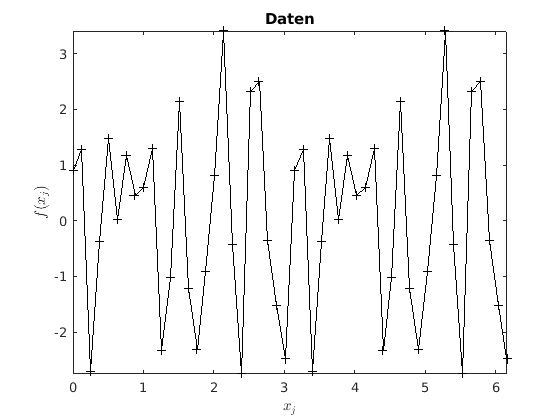

A= [1, 1.2, 1.7, -0.8];
N= [10, 18, 12, 4];
n= 50; 
[x,f]= Daten(n,A,N);

Wir bestimmen die trigonometrische Interpolation (siehe Buch)

     $T_n(f;x)=\sum_{j=0}^{n-1} d_j(f) e^{ij x}$.

Die Beträge der Fourierkoeffizienten $|d_j(f)|$, $j=0,\ldots,n-1,$ werden gezeigt.

Beachte, dass die Symmetrie-Eigenschaft $|d_j(f)|=|d_{n-j}(f)|$ gilt und dass die Werte $j \leq \frac12 n$ mit $d_j(f) \neq 0$ gerade den Frequenzen $N_i$  ($i=1,2,3,4$) entsprechen.  Außerdem gibt es direkte einfache  Zusammenhänge zwischen $|d_j(f)|$ und den Amplituden $|A_i|,~i=1,2,3,4.$

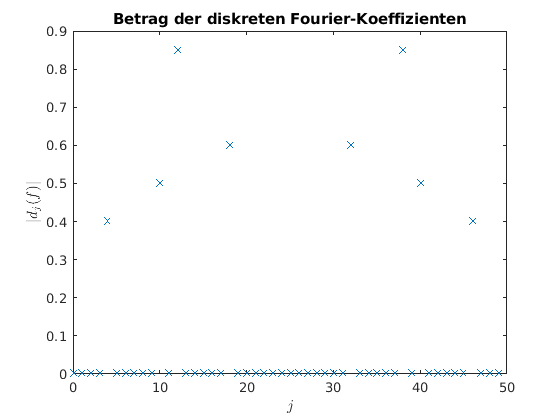

D = 1/n*fft(f); % Bestimmung der diskreten Fourierkoeffizienten d_j(f)
absD =abs(D);
J =(0:n-1);
plot(J,absD,'x') 
title('Betrag der diskreten Fourier-Koeffizienten');
xlabel('$j$','Interpreter','latex');
ylabel('$|d_j(f)|$','Interpreter','latex');

Wir betrachten den Effekt eines verrauschten Signals. Dazu werden die exakten Daten mit stochastischen Fehlern der Größenordnung $\delta$ gestört. 

Die gestörten Daten werden geplottet und die entsprechenden diskreten Fourier-Koeffizienten berechnet und gezeigt.

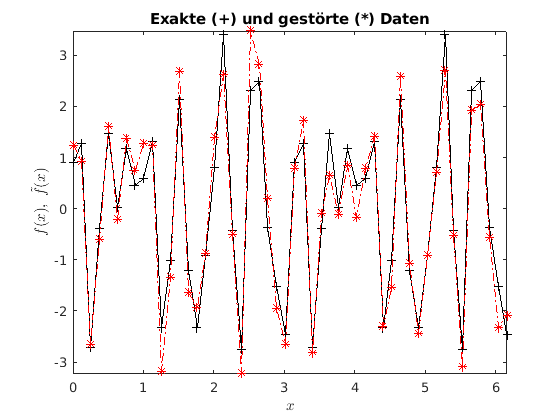

delta=0.2;
ftilde = f + delta*randn(size(f));
visualizeDaten(x,f,ftilde);

fprintf('\nGröße des Datenfehlers (gewichtete Euklidische Norm): %8.4e\n', ...
    1/sqrt(n)*norm(f - ftilde));


Größe des Datenfehlers (gewichtete Euklidische Norm): 4.3588e-01


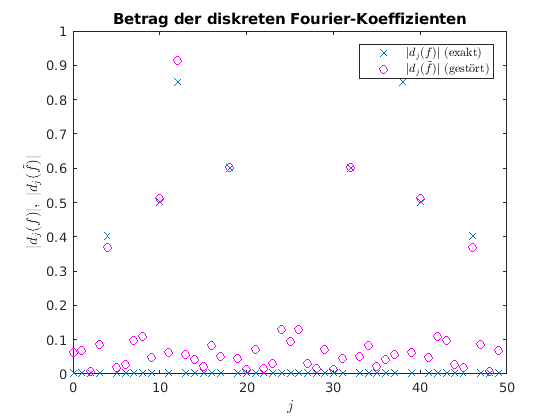


Dtilde = 1/n*fft(ftilde);
absDtilde = abs(Dtilde);
visualizeKoeff(J,absD,absDtilde);

fprintf('\nDifferenz in Fourier-Koeffizienten (Euklidische Norm): %8.4e\n', ...
    norm(D-Dtilde));


Differenz in Fourier-Koeffizienten (Euklidische Norm): 4.3588e-01


# Aktivität:

Variieren Sie die Frequenzen $N_i$, Amplituden $A_i$ und Größe der Datenstörung $\delta$ und beobachten Sie die Effekte davon. Vergleichen Sie den Datenfehler mit der Euklidischen Norm der Differenz in den Fourierkoeffizienten. Durch Drücken von "Run" bzw. F5 können Sie das Experiment für einen anderen Datenfehler wiederholen.

function [x,f]=Daten(n,A,N)
% erzeuge und plotte Daten
x = (0:n-1)*(2*pi/n);        
f = A(1)*sin(N(1)*x) + A(2)*sin(N(2)*x) + A(3)*cos(N(3)*x) + A(4)*cos(N(4)*x);
plot(x,f,'k+-');
axis tight;
title('Daten')
xlabel('$x_j$','Interpreter','latex');
ylabel('$f(x_j)$','Interpreter','latex')
end

function visualizeDaten(x,f,ftilde)
plot(x,f,'k+-', x,ftilde,'r*-.');
axis tight;
title('Exakte (+) und gestörte (*) Daten')
xlabel('$x$','Interpreter','latex');
ylabel('$f(x),~ \tilde f(x)$','Interpreter','latex');
end

function visualizeKoeff(J,absD,absDtilde)
plot(J,absD,'x',J,absDtilde,'om'); 
title('Betrag der diskreten Fourier-Koeffizienten');
xlabel('$j$','Interpreter','latex');
ylabel('$|d_j(f)|,~ |d_j(\tilde f)|$','Interpreter','latex');
leg1=legend('$|d_j(f)|$ (exakt)','$|d_j(\tilde f)|$ (gest\"{o}rt)');
set(leg1,'Interpreter','latex');
end